clear; clear path; clc;
% cd('~/git/hardDiskControl/continuousTimeControl/distReject/')
load('../../data/plantTF.mat');
addpath ../../funcs/;
format shortG


[A,B,C,D]=tf2ss([200 10^6],[1 200 10^6 0 0])

A =         -200    -1000000           0           0
           1           0           0           0
           0           1           0           0
           0           0           1           0


B =      1
     0
     0
     0


C =            0           0         200     1000000


D =      0


sys = ss(A,B,C,D);
riseTime = 0.052333; %seconds
dsys = c2d(sys,riseTime/10)

dsys =
 
  A = 
               x1          x2          x3          x4
   x1      0.3337       524.1           0           0
   x2  -0.0005241      0.2289           0           0
   x3   7.711e-07  -0.0003699           1           0
   x4   5.603e-09   1.892e-06    0.005233           1
 
  B = 
               u1
   x1  -0.0005241
   x2   7.711e-07
   x3   5.603e-09
   x4    1.18e-11
 
  C = 
          x1     x2     x3     x4
   y1      0      0    200  1e+06
 
  D = 
       u1
   y1   0
 
Sample time: 0.0052333 seconds
Discrete-time state-space model.


Pz = tf(dsys)

Pz =
 
  1.292e-05 z^3 + 7.514e-06 z^2 - 3.633e-06 z + 4.791e-06
  -------------------------------------------------------
      z^4 - 2.563 z^3 + 2.476 z^2 - 1.265 z + 0.3511
 
Sample time: 0.0052333 seconds
Discrete-time transfer function.
Model Properties


P = 10;
I = 0;
D = 50;
N = 150;
Cs = pidGen(P,I,D,N,1);
Cz = (c2d(Cs,riseTime/10))

Cz =
 
  7510 z - 7505
  -------------
   z - 0.4561
 
Sample time: 0.0052333 seconds
Discrete-time transfer function.
Model Properties


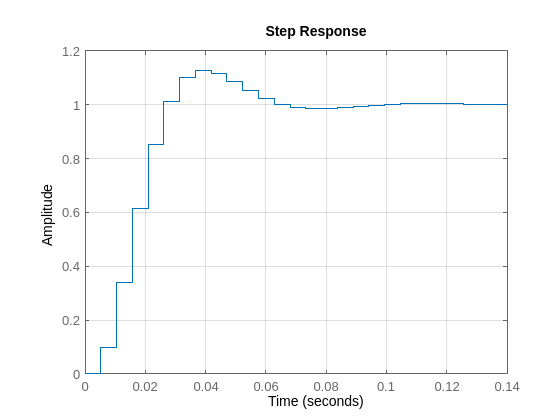

figure(1);clf; hold on;
step(Pz*Cz/(1+Pz*Cz)); grid on;


stepinfo(Pz*Cz/(1+Pz*Cz))

ans = struct with fields:
         RiseTime: 0.0157
    TransientTime: 0.0628
     SettlingTime: 0.0628
      SettlingMin: 0.98655
      SettlingMax: 1.1273
        Overshoot: 12.582
       Undershoot: 0
             Peak: 1.1273
         PeakTime: 0.036633


riseTime = 0.022295;
dsys = c2d(sys,riseTime/10);
Pz = tf(dsys);


P = 1100;
I = 1200;
D = 40;
N = 120;
Cs = pidGen(P,I,D,N,1);
Cz = c2d(Cs,riseTime/10)

Cz =
 
  5900 z^2 - 1.154e04 z + 5640
  ----------------------------
     z^2 - 1.765 z + 0.7653
 
Sample time: 0.0022295 seconds
Discrete-time transfer function.
Model Properties


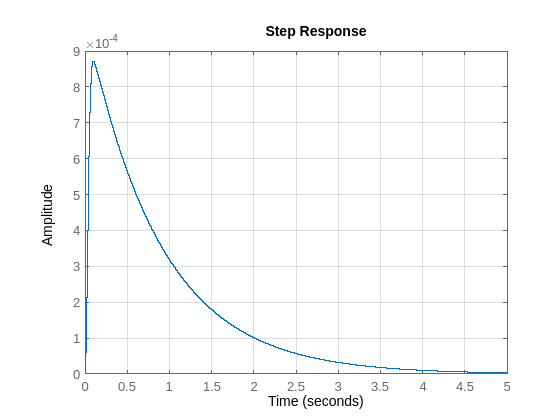

figure(2);clf; hold on;
step(Pz/(1+Pz*Cz)); grid on;

a = stepinfo(Pz/(1+Pz*Cz))

a = struct with fields:
         RiseTime: 0.0022295
    TransientTime: 3.1726
     SettlingTime: NaN
      SettlingMin: 2.2395e-06
      SettlingMax: 0.00087114
        Overshoot: 9349.6
       Undershoot: 0
             Peak: 0.00087114
         PeakTime: 0.098098
